h_nt = h_protein;
c_nt = codons;

scoresNT = [];
for i=1: length(h_nt)
    for j=1:length(c_nt)
        scoresNT = [scoresNT; i,j,nwalign(char(h_nt(i,1)), char(c_nt(j,1)), 'scoringmatrix','blosum30','gapopen',5,'extendgap',5,'ALPHABET','NT')];
    end
end

total_combinations = length(scoresNT)

total_combinations = 99

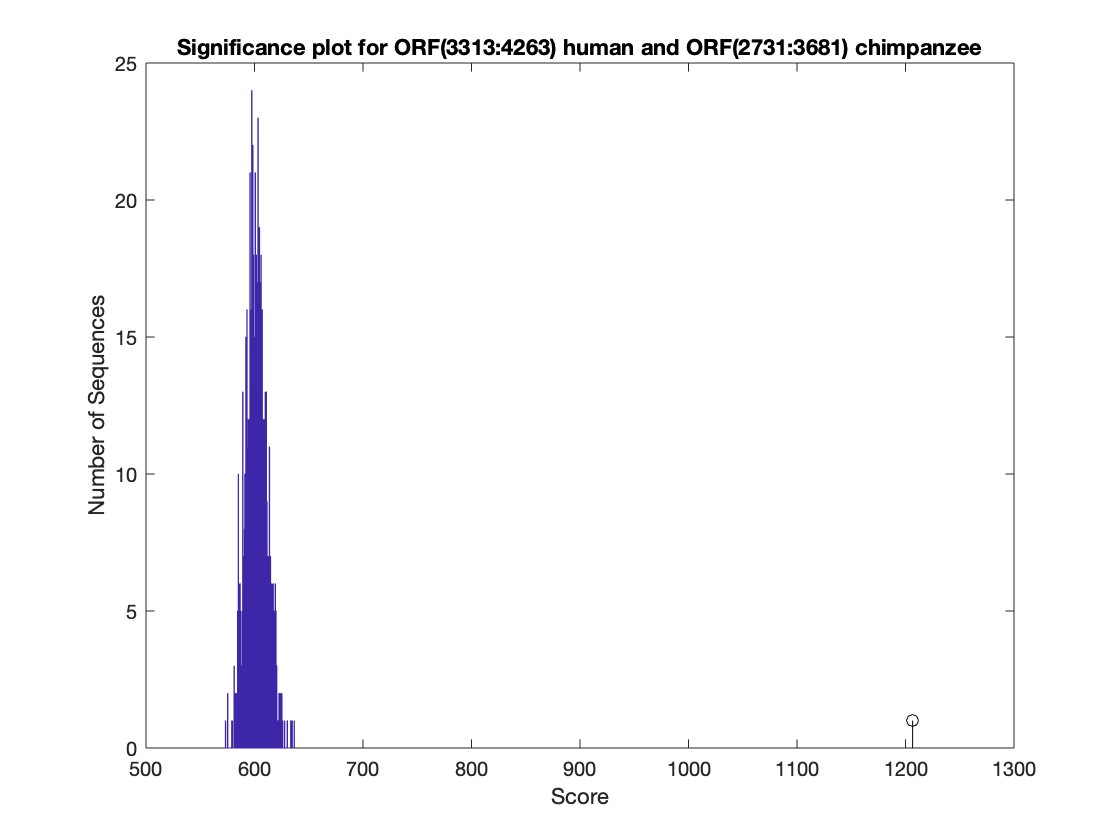

scoreNT = 1.2066e+03

p_value = 0

ans = "ORF in position(3313:4263) in human is homologous to ORF in position (2731:3681) in chimpanzee"

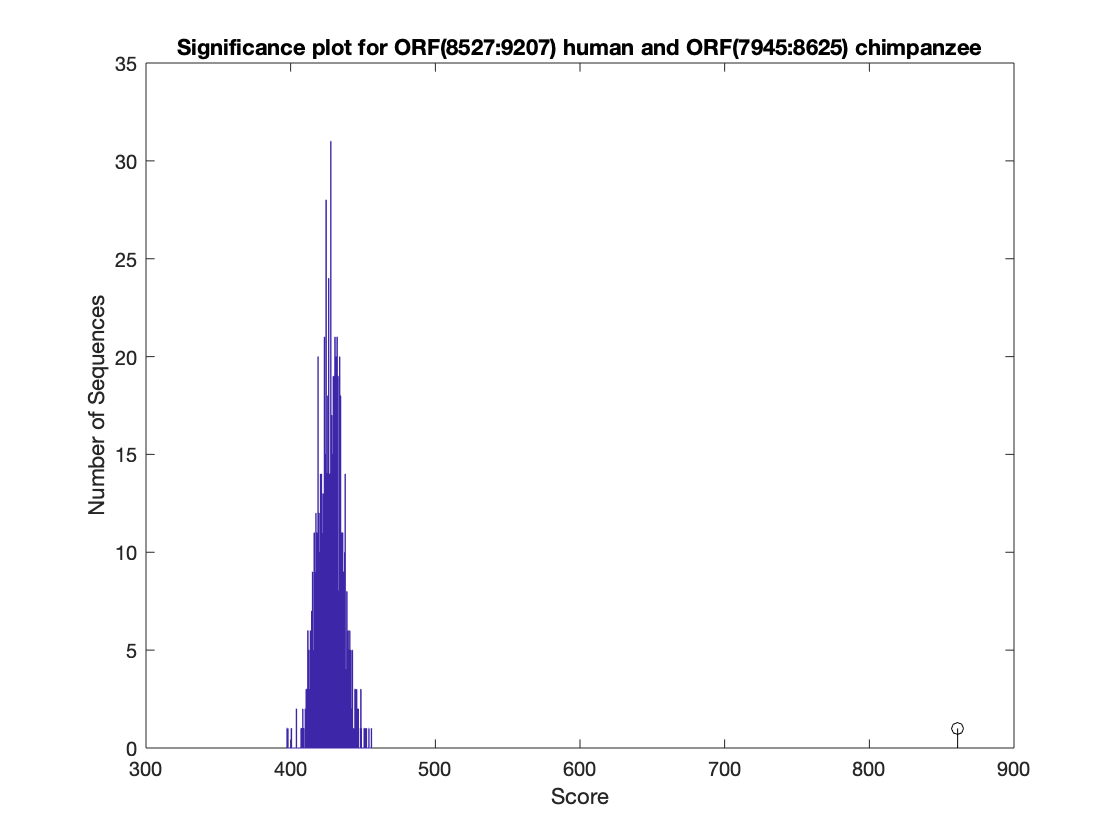

scoreNT = 861

p_value = 0

ans = "ORF in position(8527:9207) in human is homologous to ORF in position (7945:8625) in chimpanzee"

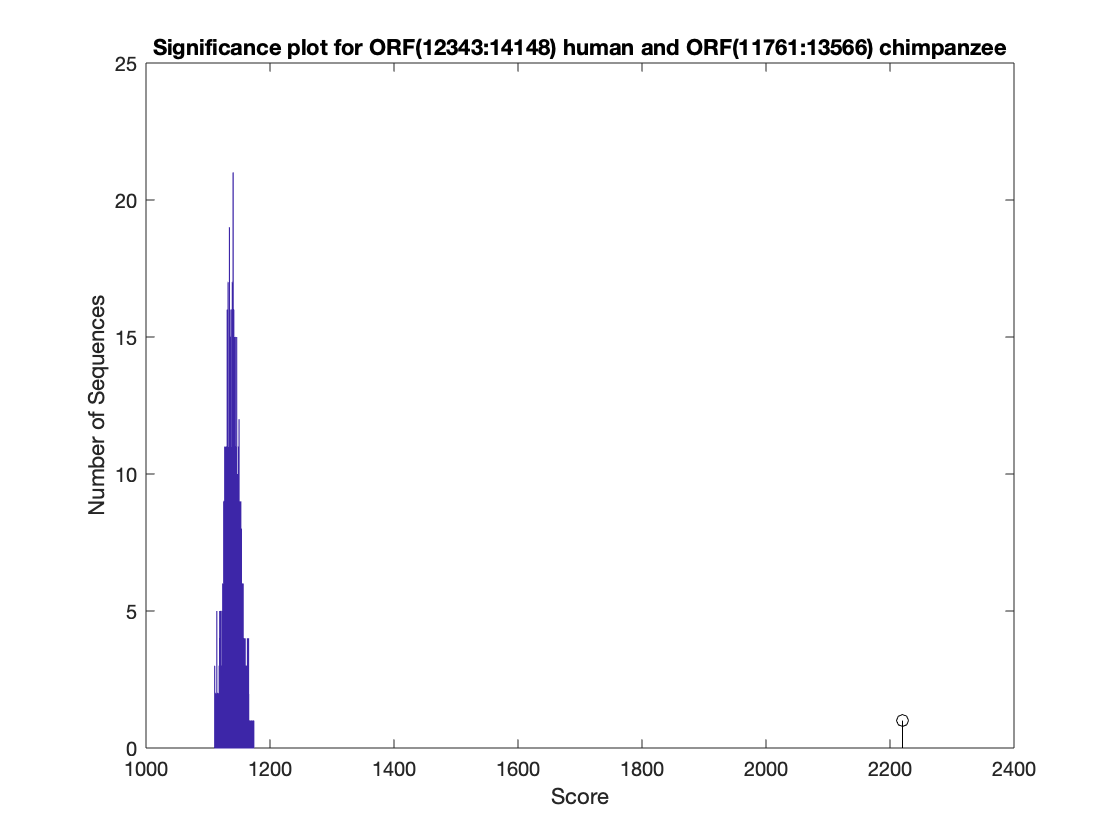

scoreNT = 2.2202e+03

p_value = 0

ans = "ORF in position(12343:14148) in human is homologous to ORF in position (11761:13566) in chimpanzee"

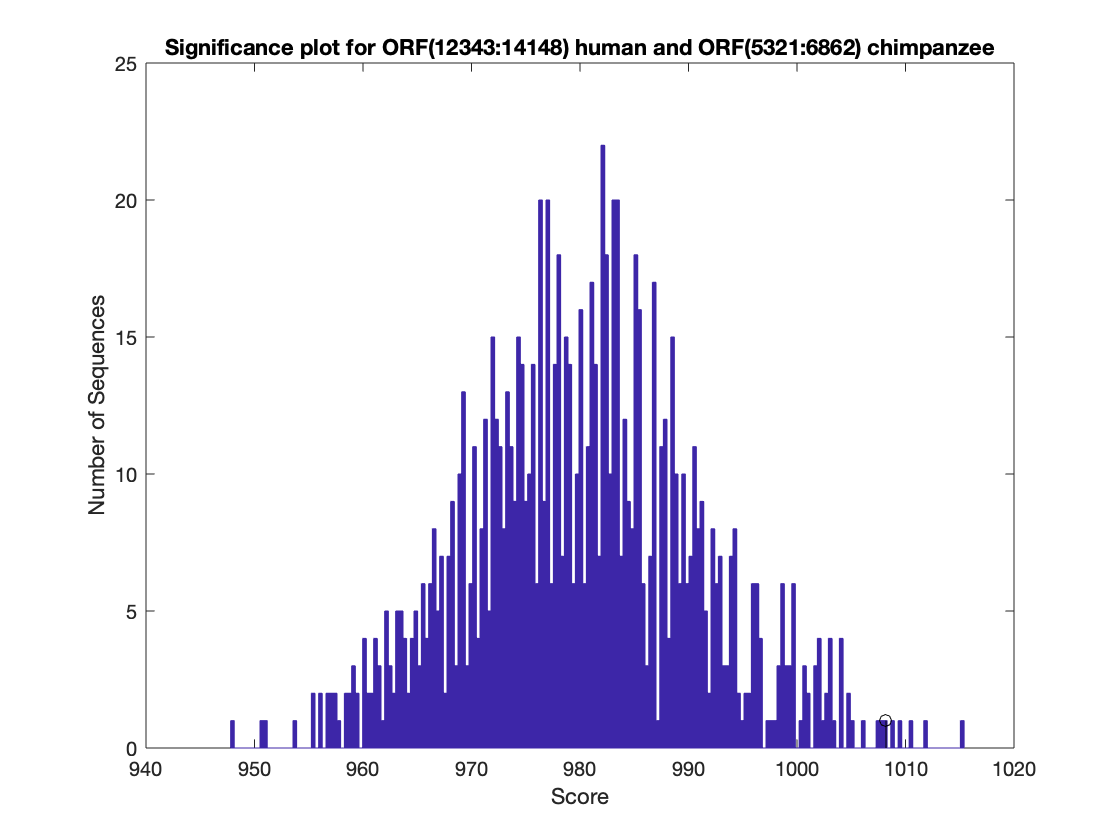

scoreNT = 1.0082e+03

p_value = 0.0050

ans = "ORF in position(12343:14148) in human is homologous to ORF in position (5321:6862) in chimpanzee"

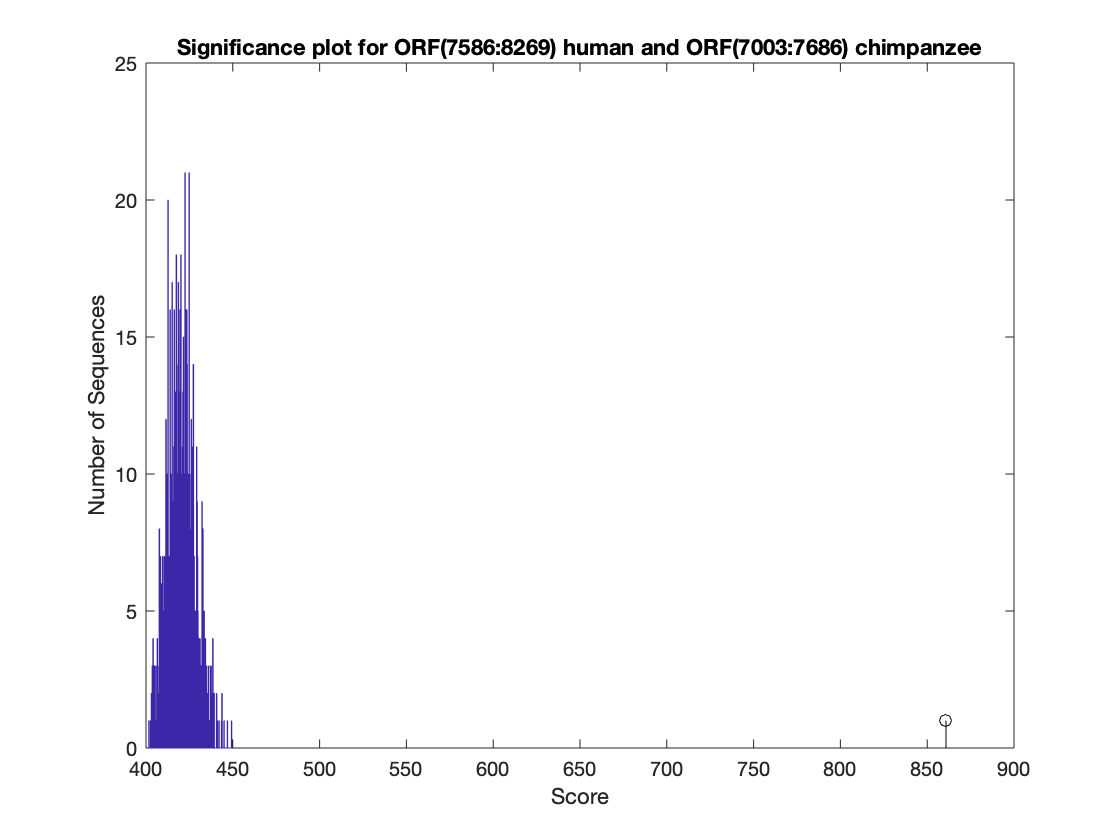

scoreNT = 860.8000

p_value = 0

ans = "ORF in position(7586:8269) in human is homologous to ORF in position (7003:7686) in chimpanzee"

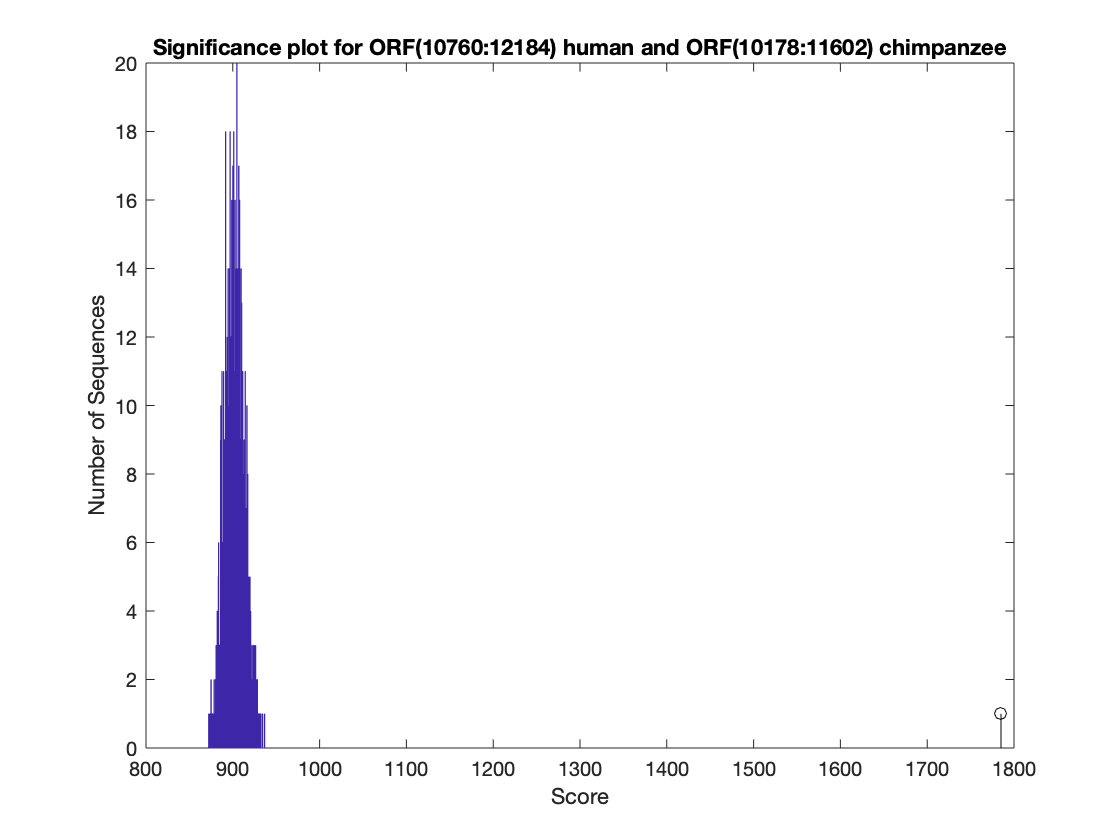

scoreNT = 1785

p_value = 0

ans = "ORF in position(10760:12184) in human is homologous to ORF in position (10178:11602) in chimpanzee"

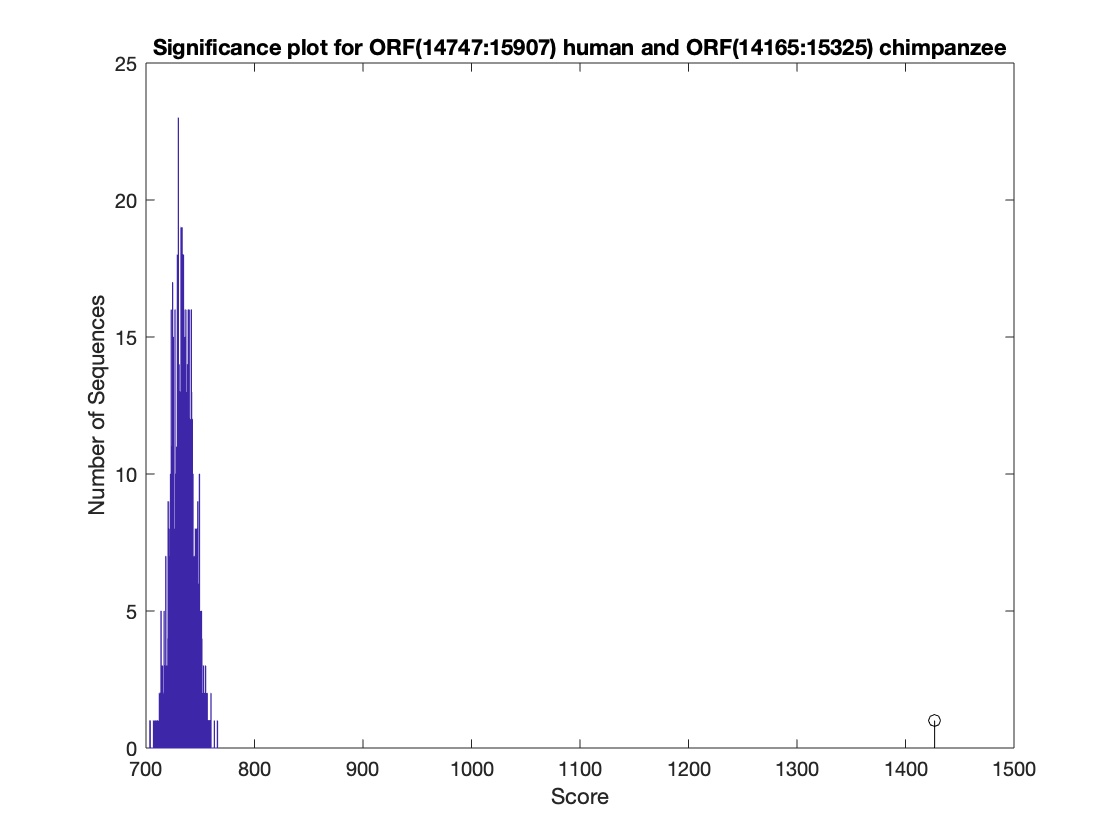

scoreNT = 1.4268e+03

p_value = 0

ans = "ORF in position(14747:15907) in human is homologous to ORF in position (14165:15325) in chimpanzee"

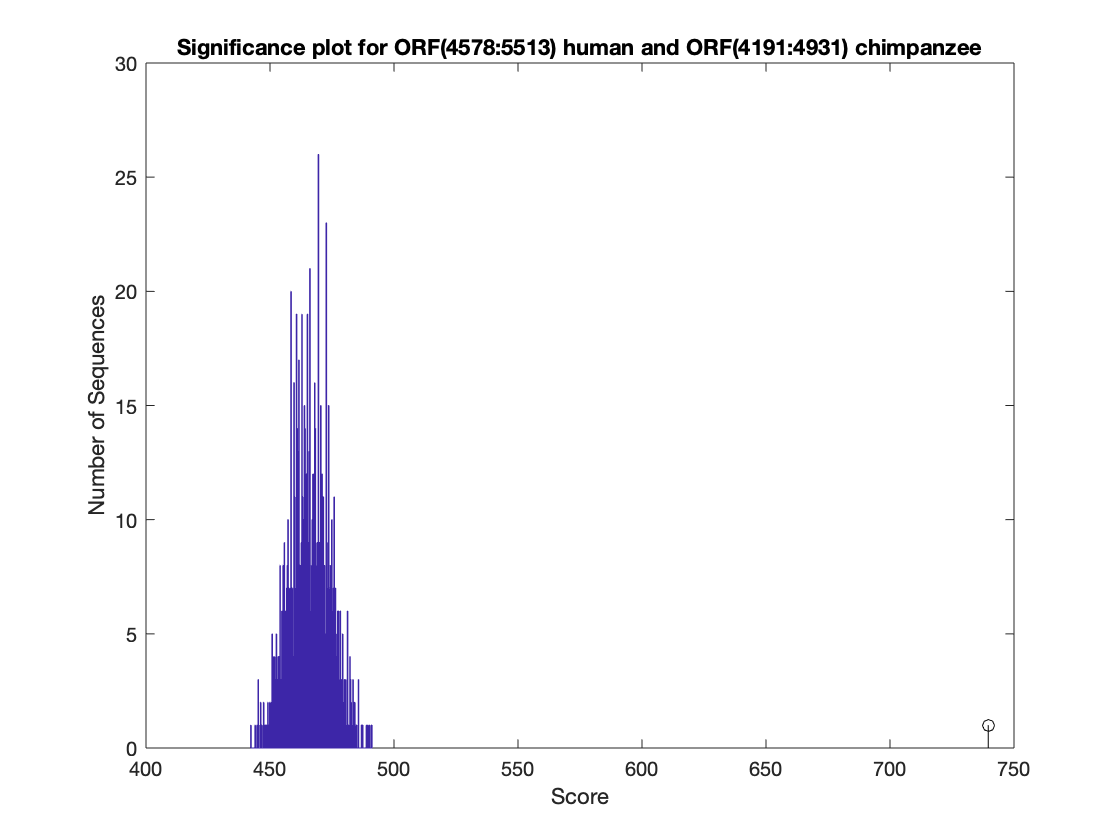

scoreNT = 739.6000

p_value = 0

ans = "ORF in position(4578:5513) in human is homologous to ORF in position (4191:4931) in chimpanzee"

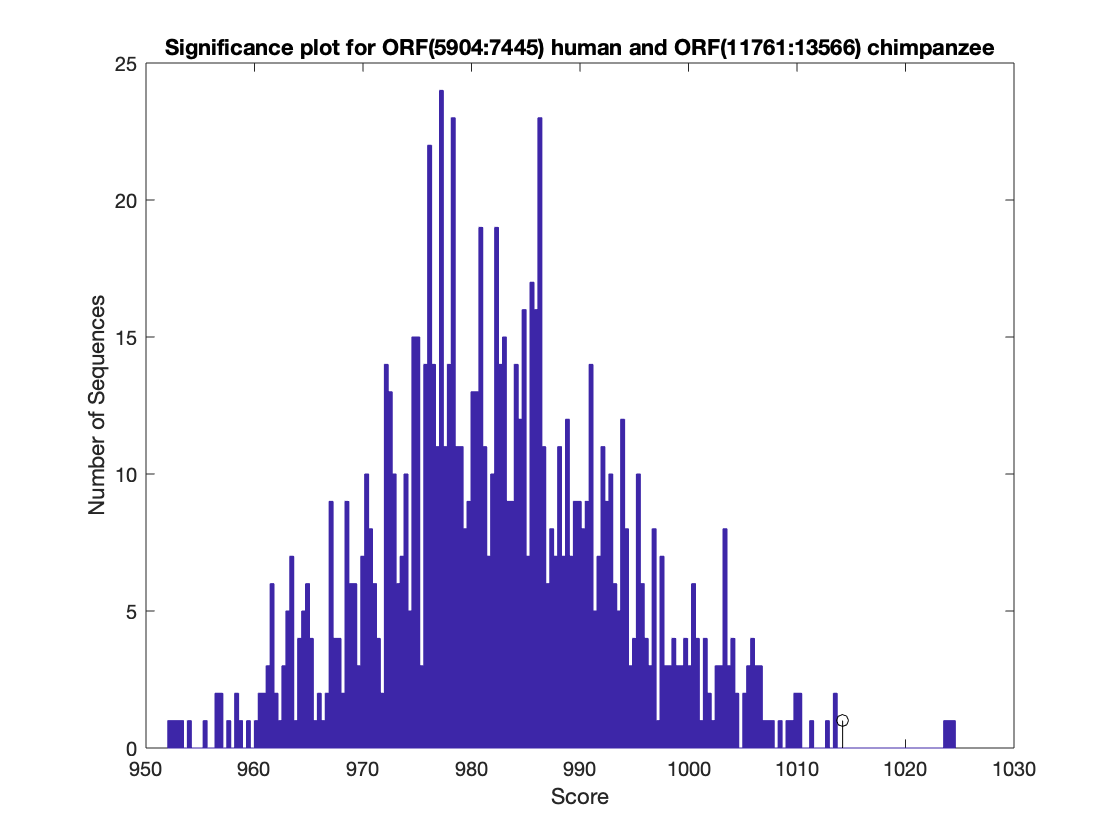

scoreNT = 1.0142e+03

p_value = 0.0030

ans = "ORF in position(5904:7445) in human is homologous to ORF in position (11761:13566) in chimpanzee"

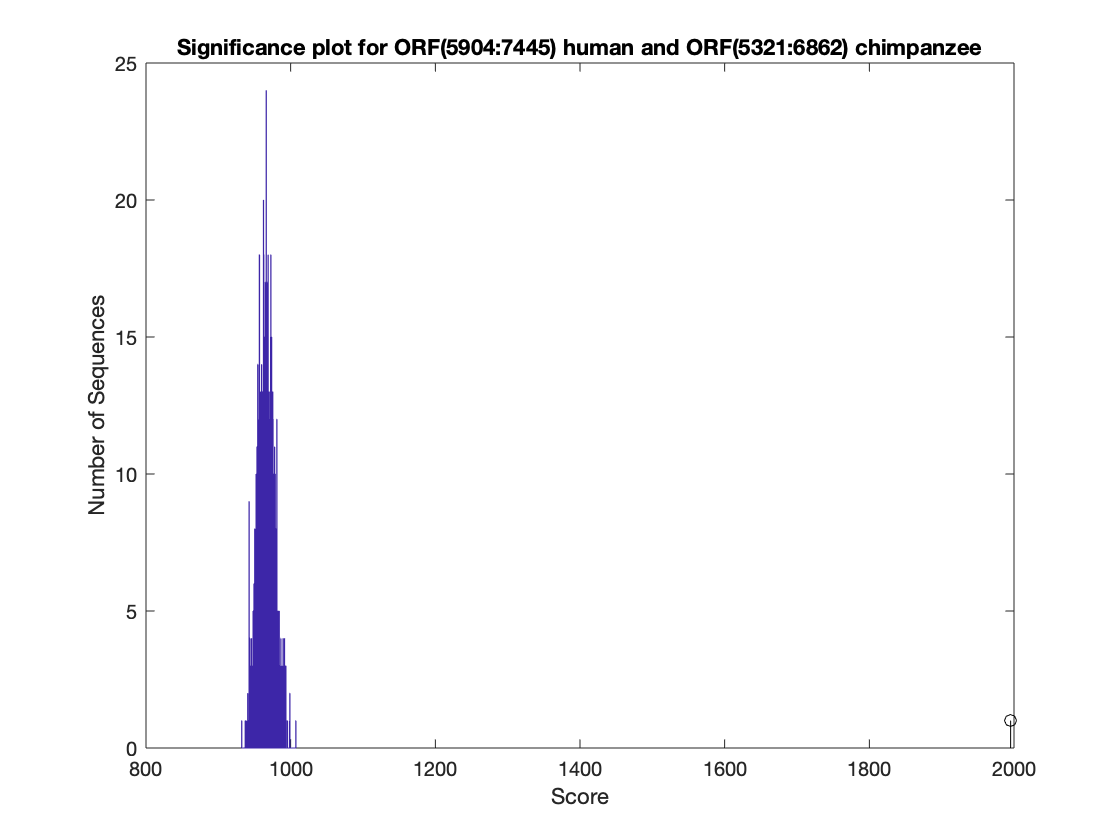

scoreNT = 1.9954e+03

p_value = 0

ans = "ORF in position(5904:7445) in human is homologous to ORF in position (5321:6862) in chimpanzee"

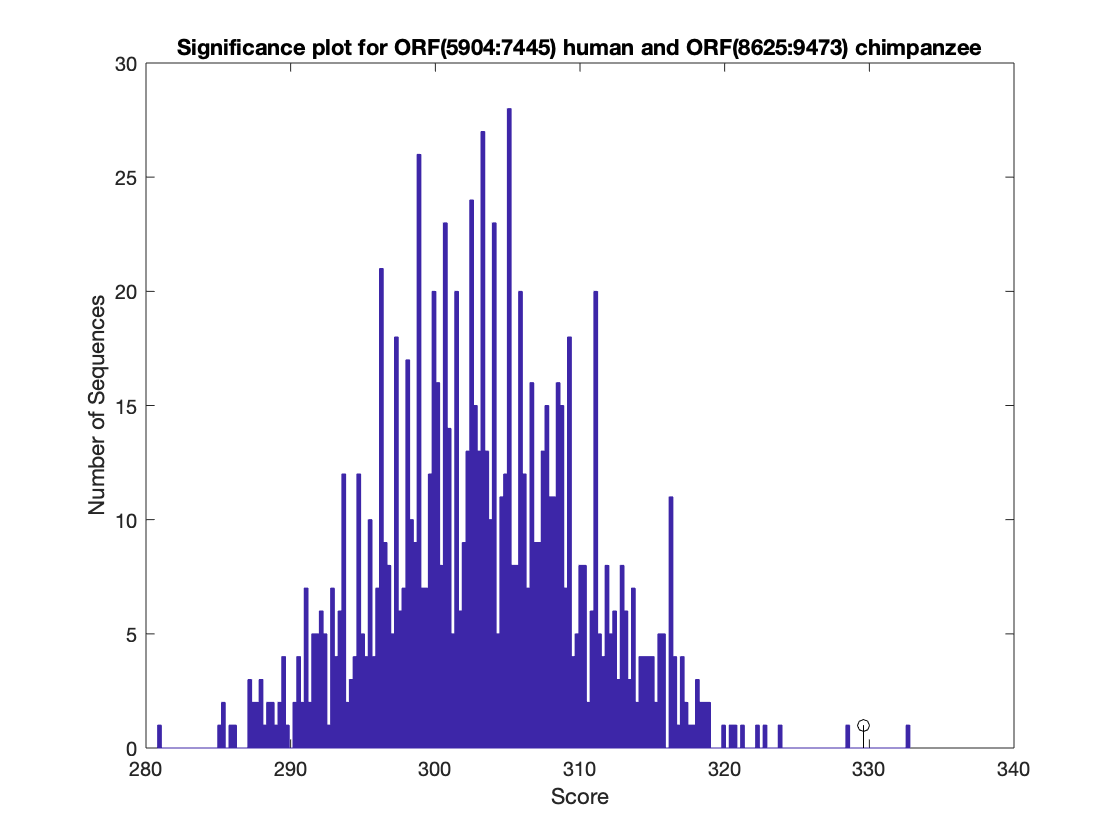

scoreNT = 329.6000

p_value = 1.0000e-03

ans = "ORF in position(5904:7445) in human is homologous to ORF in position (8625:9473) in chimpanzee"

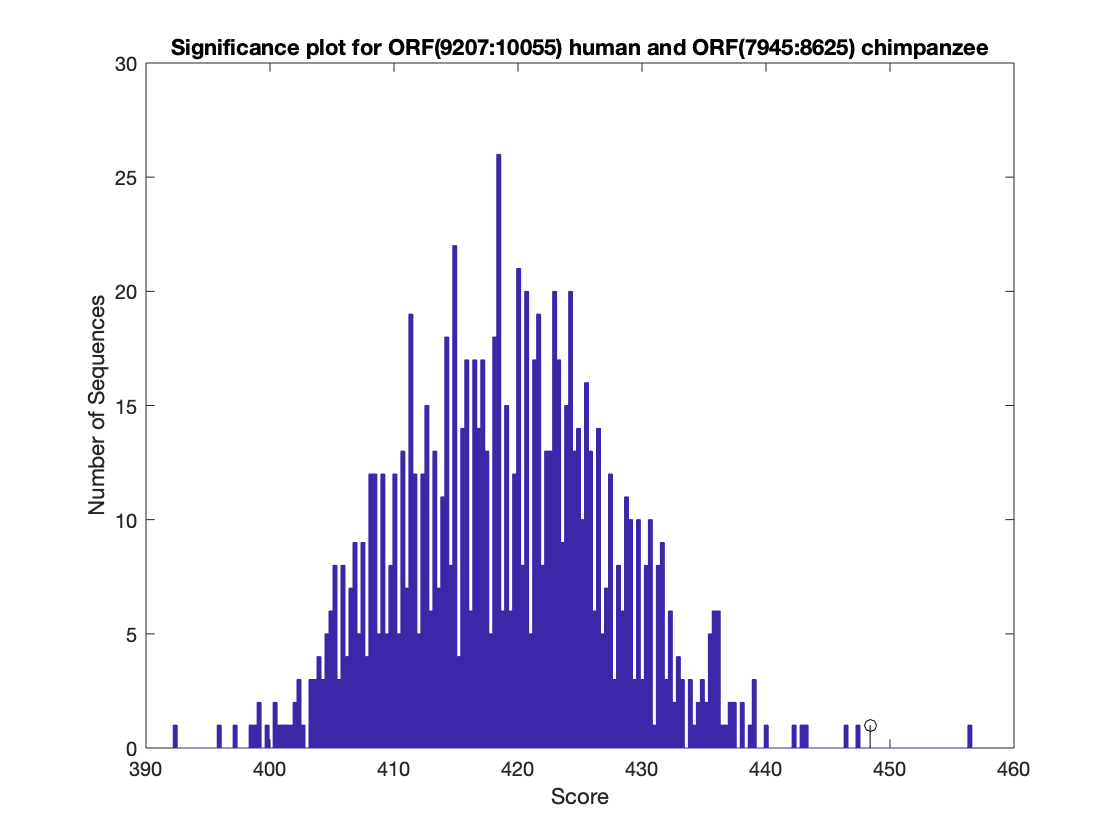

scoreNT = 448.4000

p_value = 1.0000e-03

ans = "ORF in position(9207:10055) in human is homologous to ORF in position (7945:8625) in chimpanzee"

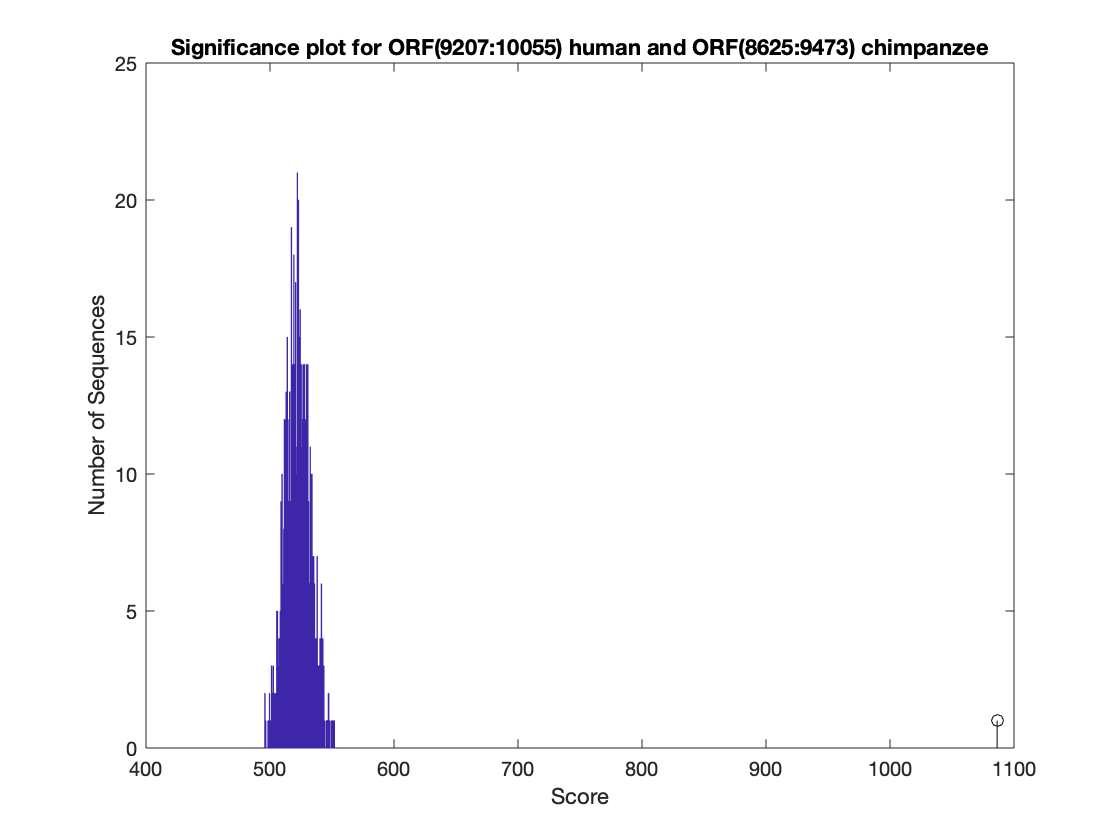

scoreNT = 1.0864e+03

p_value = 0

ans = "ORF in position(9207:10055) in human is homologous to ORF in position (8625:9473) in chimpanzee"

for i=1:total_combinations
    h = scoresNT(i,1);
    c = scoresNT(i,2);
    scoreNT = scoresNT(i,3);
    human_NT = char(h_nt(h,1));
    chimp_NT = char(c_nt(c,1));
    n = 1000;
    globalscores = zeros(n,1);
    chimpLen = length(chimp_NT);
    for j = 1:n
        perm = randperm(chimpLen);
        globalscores(j) = nwalign(human_NT,chimp_NT(perm),'scoringmatrix','blosum30','gapopen',5,'extendgap',5,'ALPHABET','NT');
    end
    p_value = length(find(globalscores >= scoreNT)) / 1000;
    if (p_value < 0.01)
        figure
        buckets = ceil(n/5);
        hist(globalscores,buckets)
        hold on;
        stem(scoreNT,1,'k')
        xlabel('Score'); ylabel('Number of Sequences');
         titleStr = strcat('Significance plot for ORF(' ,h_nt(h,2),':',h_nt(h,3), ...
             ') human and ORF(',c_nt(c,2),':',c_nt(c,3), ') chimpanzee');
        title(titleStr);
        hold off;
        [score1, alignment] = nwalign(human_NT, chimp_NT, ...
            'scoringmatrix','blosum30','gapopen',5,'extendgap',5,'ALPHABET','NT');
        showalignment(alignment)
        scoreNT
        p_value
        strcat('ORF in position(' ,h_aminoacid(h,2),':',h_aminoacid(h,3), ...
              ') in human is homologous to ORF in position (',aminoacid(c,2),':',aminoacid(c,3), ') in chimpanzee')
    end
end